# Demonstration of a PnP operation for a DGU Network

clear
close all
% USE MOSEK as solver (ADD to path)
addpath 'C:\Program Files\Mosek\9.3\toolbox\R2015aom'
addpath(genpath(cd));

- Initialize Network: Complete configuration of the network with all the electrical parameters is load from a text file

utils = utilityFunctions;
PnP = SimFunctionsPnP;
config = "DISTRIBUTED"; % distributed config, for plot function
filename = 'config_DGU_1.txt';
[nb_subsystems, Vin,R,L,C, Vmax, Vmin, Imax, Imin] = utils.importData(filename);

    {'subsystems'}    {'Vin'}    {'R     '}    {'L     '}    {'C    '}    {'Vmax'}    {'Vmin'}    {'Imax'}    {'Imin'}

    6.0000  100.0000    0.0030    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0015    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0017    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0016    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0015    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0016    0.0001    0.0001   52.0000   49.0000   10.0000         0



dguNet = DGU_network(nb_subsystems); % Instantiate a DGU NETWORK class

- Set references $V_r$ [V] to converge to and load current $I_l$ [A]

Vr = linspace(49.975, 50.1, nb_subsystems)% references

Vr =    49.9750   50.0000   50.0250   50.0500   50.0750   50.1000


Il = linspace(3.5, 5.5, nb_subsystems)

Il =     3.5000    3.9000    4.3000    4.7000    5.1000    5.5000


% set Electrical parameters and Dynamics for ALL the subsystems in the network
for i=1:nb_subsystems
    dguNet = dguNet.initElecParam(i,Vin(i), Vr(i), Il(i), R(i), C(i), L(i), ...
                                  Vmax(i), Vmin(i), Imax(i), Imin(i));
end

### A) For now consider only 5 active DGU out of 6

Parameters for MPC simulation

simStart = 1;
length_sim = 25;

Network Configuration

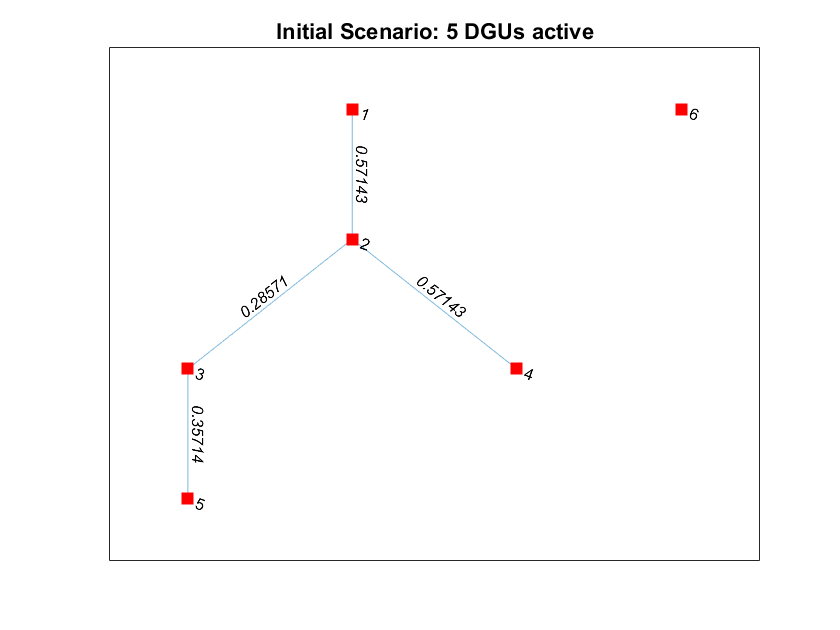

activeDGU_scen1 = 1:1:5; % Initially, 5 DGUs are active
Rij_mat = zeros(nb_subsystems);
Rij_mat(1,2) = 1.75; Rij_mat(2,3) = 3.5; Rij_mat(2,4) = 1.75; 
Rij_mat(3,5) = 2.8; 
Rij_mat = Rij_mat + tril(Rij_mat',1); % Non directed graph, symmetric matrix
dguNet = dguNet.setConnectionsGraph(Rij_mat); % set links between DGU
dguNet = dguNet.setActiveDGU(activeDGU_scen1); % define which DGUs are active
figure()
plot(dguNet.NetGraph, 'EdgeLabel', dguNet.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title("Initial Scenario: 5 DGUs active");

dguNet = dguNet.initDynamics(); % initialize dynamics

For passivity based MPC, constraints are not in $\Delta$ Formulation 

delta_config = false; % not in delta configuration
dguNet = dguNet.compute_Ref_Constraints(delta_config);

- Use passivity to find the local passive feedback gains $K_i$ and $P_i$ s.t. $V_i(x_i) = x_i^T P_i x_i$

dguNet = PnP.setPassiveControllers(dguNet);

ans = "K1"

   -0.6387   -0.1384



ans = "P1"

   49.8098    3.2712
    3.2712    1.1312

minimum eigenvalue of dissipation rate 8.95e-01 


ans = "K2"

   -0.0103   -0.1017



ans = "P2"

    2.9528    0.5446
    0.5446    4.1612

minimum eigenvalue of dissipation rate 9.97e-02 


ans = "K3"

   -0.4957   -0.1504



ans = "P3"

   24.7525    2.1795
    2.1795    1.0425

minimum eigenvalue of dissipation rate 8.22e-01 


ans = "K4"

   -0.1136   -0.1017



ans = "P4"

   11.4766    1.4834
    1.4834    1.8648

minimum eigenvalue of dissipation rate 6.07e-01 


ans = "K5"

   -0.6108   -0.1390



ans = "P5"

   67.5107    4.6917
    4.6917    1.6810

minimum eigenvalue of dissipation rate 1.32e+00 


Compute Qi and Ri matrices in a distributed fashion to ensure global aymptotic stability

passivity = true;
[x0, Q_Ni, Ri] = utils.tuningParam(dguNet, delta_config, passivity);

Qi and Ri found to guarantee asympt. stabilityof the global system 


- Use the tracking MPC with reconfigurable terminal ingredients  to converge to reference from the initial state

control_type = "MPC with reconfigurable terminal ingredients";
[X, U, ~] = PnP.mpc_DGU_tracking(@trackingMPC_reconf_admm, x0, length_sim,...
                                             dguNet, Q_Ni, Ri);

--INFO: Using controller trackingMPC_reconf_admm -- 
 ---- Simulation step 1 ---- 
Time elapsed to converge 1.007112e+01 and number of iterations 41 
---- Simulation step 2 ---- 
Time elapsed to converge 1.010511e+01 and number of iterations 37 
---- Simulation step 3 ---- 
Time elapsed to converge 1.009317e+01 and number of iterations 39 
---- Simulation step 4 ---- 
Time elapsed to converge 1.019296e+01 and number of iterations 32 
---- Simulation step 5 ---- 
Time elapsed to converge 1.002303e+01 and number of iterations 46 
---- Simulation step 6 ---- 
Time elapsed to converge 1.024171e+01 and number of iterations 41 
---- Simulation step 7 ---- 
Time elapsed to converge 1.002269e+01 and number of iterations 38 
---- Simulation step 8 ---- 
Time elapsed to converge 6.004364e+00 and number of iterations 49 
---- Simulation step 9 ---- 
Time elapsed to converge 3.380858e+00 and number of iterations 49 
---- Simulation step 10 ---- 
Time elapsed to converge 3.436840e+00 and number of 

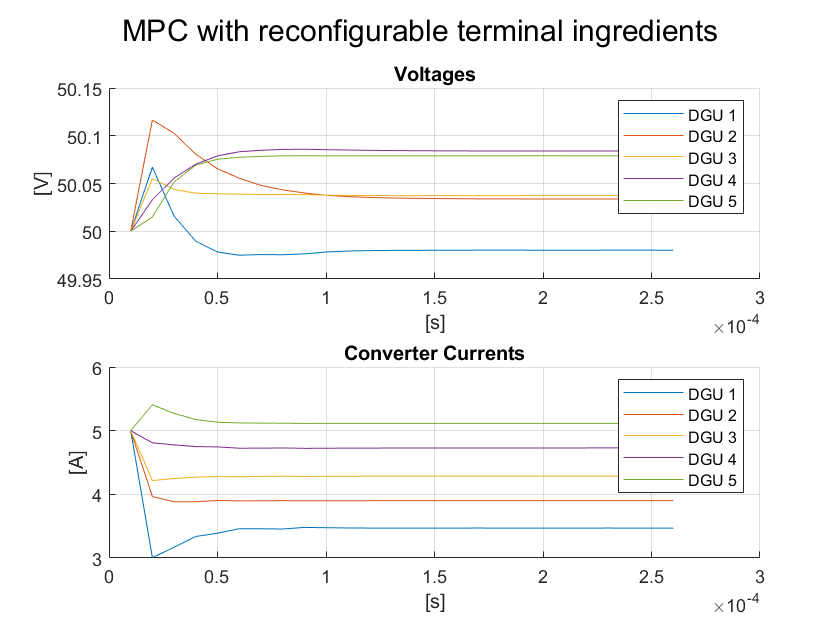

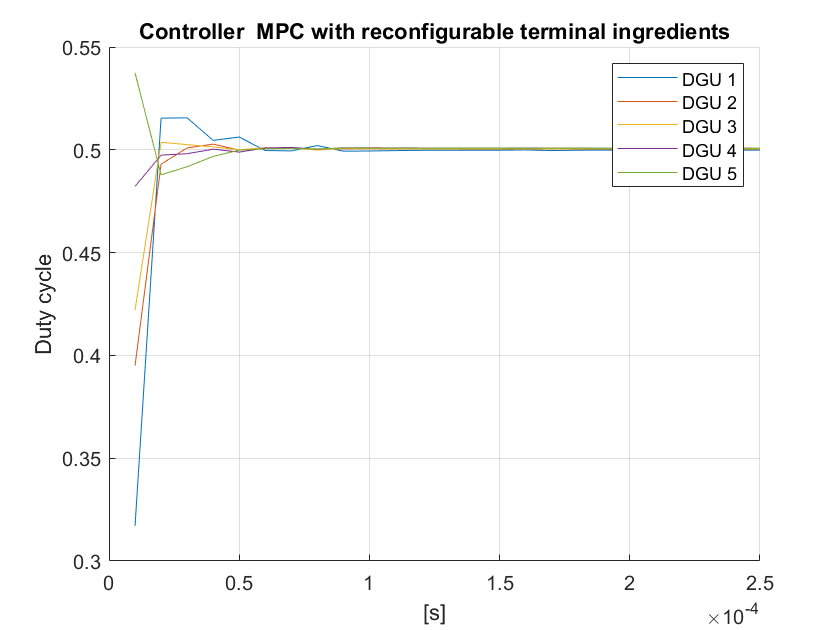

dguNet.plot_DGU_system(X,U, config, control_type, dguNet, simStart, dguNet.activeDGU); % plot results

- **Compare to **$\Delta$ **Formulation with offline computed terminal set and terminal cost**

delta_config = true;
use_passivity = false;
[x0_delta, Q_Ni, Ri] = utils.tuningParam(dguNet, delta_config, use_passivity);
dguNet_delta = dguNet;
dguNet_delta = dguNet_delta.compute_Ref_Constraints(delta_config);
[dguNet_delta, Gamma_Ni, alpha_i] = offlineComputeTerminalSet(Q_Ni, Ri, dguNet_delta);

ans = "Local feedback control laws K_N1"

   1.0e-03 *

         0         0    0.3814         0



ans = "Local feedback control laws K_N2"

   1.0e-03 *

    0.5724         0         0         0    0.2862   -0.0000    0.5724         0



ans = "Local feedback control laws K_N3"

   1.0e-03 *

    0.2555    0.0000         0         0    0.3194         0



ans = "Local feedback control laws K_N4"

   1.0e-03 *

    0.4615    0.0000         0         0



ans = "Local feedback control laws K_N5"

   1.0e-03 *

    0.2591         0         0         0



fprintf("Initial terminal set constrait alpha = %d \n", alpha_i)

Initial terminal set constrait alpha = 1.507783e-01 


alpha = alpha_i*ismember(1:6, dguNet_delta.activeDGU)';
[Xdelt,Udelt, ~] = PnP.mpc_sim_DGU_delta(@mpc_delta_admm, x0_delta, length_sim, dguNet_delta,...
                         alpha, Q_Ni, Ri, Gamma_Ni);

--INFO: Using controller mpc_delta_admm -- 
 ---- Simulation step 1 ---- 
Time elapsed to converge 5.436034e-01 and number of iterations 58 
---- Simulation step 2 ---- 
Time elapsed to converge 4.998746e-01 and number of iterations 52 
---- Simulation step 3 ---- 
Time elapsed to converge 4.496378e-01 and number of iterations 47 
---- Simulation step 4 ---- 
Time elapsed to converge 4.213435e-01 and number of iterations 43 
---- Simulation step 5 ---- 
Time elapsed to converge 3.894999e-01 and number of iterations 40 
---- Simulation step 6 ---- 
Time elapsed to converge 3.556868e-01 and number of iterations 37 
---- Simulation step 7 ---- 
Time elapsed to converge 3.248790e-01 and number of iterations 34 
---- Simulation step 8 ---- 
Time elapsed to converge 3.343598e-01 and number of iterations 31 
---- Simulation step 9 ---- 
Time elapsed to converge 2.848459e-01 and number of iterations 29 
---- Simulation step 10 ---- 
Time elapsed to converge 2.506648e-01 and number of iteration

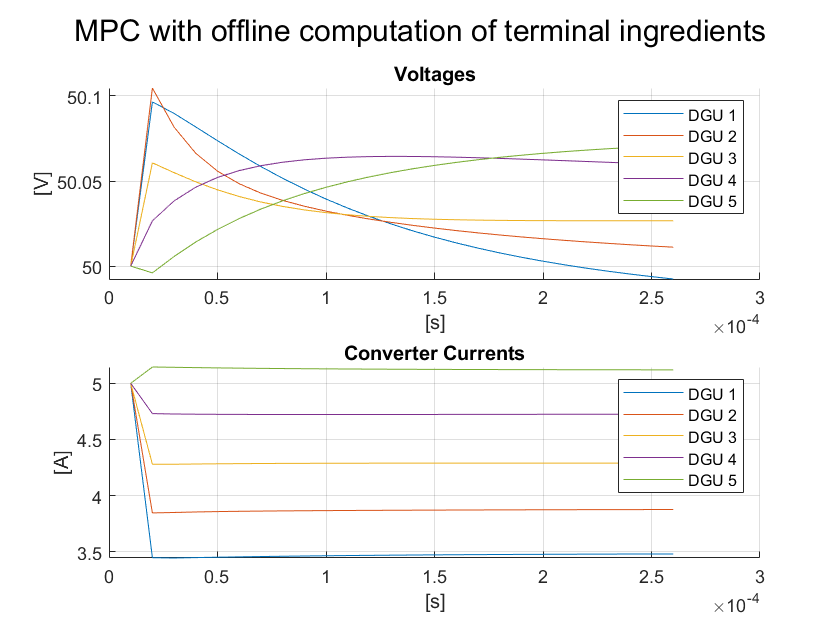

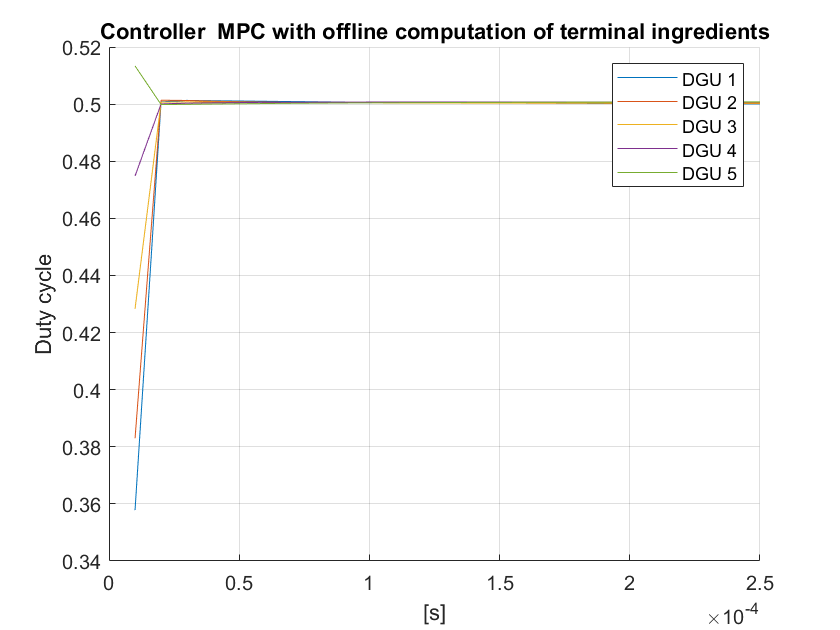

control_type = "MPC with offline computation of terminal ingredients";
config = "DISTRIBUTED";
simStart = 1;
dguNet.plot_DGU_system(Xdelt,Udelt, config, control_type, dguNet_delta, simStart, dguNet_delta.activeDGU)

### B) Scenario 2: Connect DGU 6 to DGU 3

Set all DGUs to be active. DGU 6 is now active but is not connected yet to the network

simStart2 = simStart + length_sim;
dguPos = 6;
activeDGU_scen2 = 1:1:6; % Now all the 6 DGUs are active
dguNet = dguNet.setActiveDGU(activeDGU_scen2);
dguNet2 = dguNet; % dguNet copy, with 6 active DGU but before connection

Create connection from DGU 6 to DGU 3. For this purpose, a new instance of the network class is created with the modified structure e.g. different Laplacian matrix and $A_{Ni}$ 

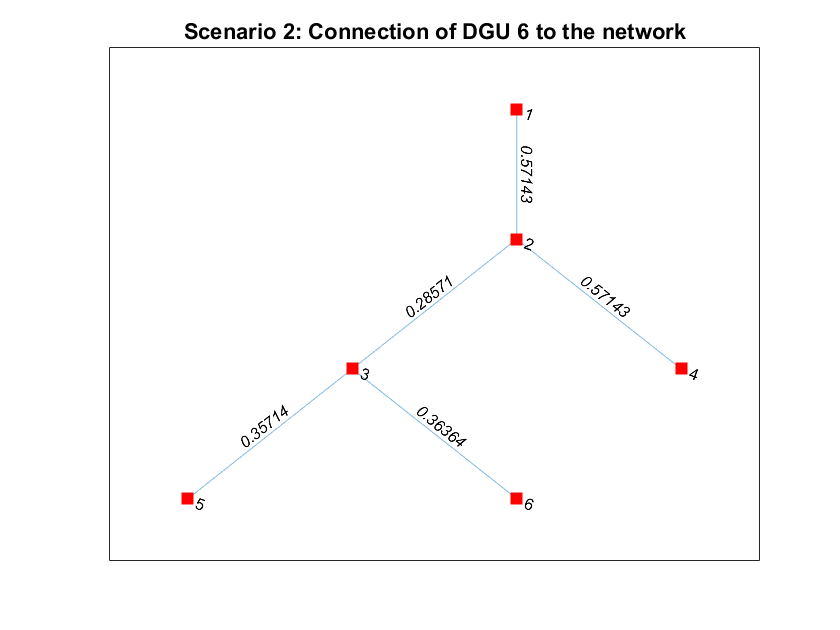

Rij_mat(3,dguPos) = 2.75; Rij_mat(dguPos,3) = Rij_mat(3,dguPos);  % New link
dguNet2 = dguNet2.setConnectionsGraph(Rij_mat);
dguNet2 = dguNet2.initDynamics(); % recompute Dynamics (changed with integration of DGU 6)
plot(dguNet2.NetGraph, 'EdgeLabel', dguNet2.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title('Scenario 2: Connection of DGU 6 to the network')

#### **PnP with passivity and Online computation of Terminal Ingredients**

- **Redesign Phase**: Compute new $K_i$ and $P_i$ of neighbors set of DGU 6 (including DGU 6 itself)

use_passivity = true;
delta_config = false;
dguNet2 = dguNet2.compute_Ref_Constraints(delta_config);
dguNet2 = PnP.redesignPhase(dguNet2, dguNet2.NetGraph,dguPos, "add");

ans = "New passive controller gain of system 3"

   -0.4650   -0.1511



ans = "P3"

   15.8061    1.3570
    1.3570    0.6736

minimum eigenvalue of dissipation rate 5.26e-01 


ans = "New passive controller gain of system 6"

   -0.5574   -0.1421



ans = "P6"

   53.5936    4.1295
    4.1295    1.6485

minimum eigenvalue of dissipation rate 1.29e+00 


Re-define Q_Ni since neighbors of DGU 3 and 6 changed. Initial values for the 5 first DGUs taken from previous simulation end. 

[x0, Q_Ni, Ri, Qi] = utils.tuningParam(dguNet2, delta_config, use_passivity); 

Qi and Ri found to guarantee asympt. stabilityof the global system 


for i = activeDGU_scen1
    x0{i} = X{end}(:,i);   %
end
disp('x0'); celldisp(x0);

x0
 
x0{1} =
 
   49.9801
   -0.0308

 
 
x0{2} =
 
   50.0338
    0.0009

 
 
x0{3} =
 
   50.0373
   -0.0139

 
 
x0{4} =
 
   50.0840
    0.0286

 
 
x0{5} =
 
   50.0790
    0.0149

 
 
x0{6} =
 
   50.0000
   -0.5000

 


- **Transition Phase**: Compute steady-state value to reach to allow the plug-in of DGU 6 (*PnP permitted). *Drive the system (the 5 initial DGU's + the 6th DGU before connection) to this steady state.

ADMM = true;
[X2_trans,U2_trans,lenSim, xs,us,alpha] = PnP.transitionPhase(x0, dguNet, dguNet2, Qi, Ri, 'reference', ADMM)

Using ADMM !
Iteration 1,  Time elapsed for each ADMM iteration 2.276930e-02 
Iteration 2,  Time elapsed for each ADMM iteration 5.145650e-02 
Iteration 3,  Time elapsed for each ADMM iteration 7.791120e-02 
Iteration 4,  Time elapsed for each ADMM iteration 1.118284e-01 
Iteration 5,  Time elapsed for each ADMM iteration 1.415263e-01 
Iteration 6,  Time elapsed for each ADMM iteration 1.700653e-01 
Iteration 7,  Time elapsed for each ADMM iteration 2.024856e-01 
Iteration 8,  Time elapsed for each ADMM iteration 2.457639e-01 
Iteration 9,  Time elapsed for each ADMM iteration 2.884033e-01 
Iteration 10,  Time elapsed for each ADMM iteration 3.167212e-01 
Iteration 11,  Time elapsed for each ADMM iteration 3.521696e-01 
Iteration 12,  Time elapsed for each ADMM iteration 3.796070e-01 
Iteration 13,  Time elapsed for each ADMM iteration 4.053215e-01 
Iteration 14,  Time elapsed for each ADMM iteration 4.423687e-01 
Iteration 15,  Time elapsed for each ADMM iteration 4.778280e-01 
Iterat

X2_trans = 1×5 cell array
    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}


U2_trans = 1×4 cell array
    {[0.4918 0.4971 0.4897 0.4898 0.5012 0.5853]}    {[0.5041 0.5015 0.5048 0.5045 0.5011 0.4883]}    {[0.5028 0.5010 0.5032 0.5033 0.5010 0.4855]}    {[0.5009 0.5007 0.5013 0.5021 0.5009 0.4934]}


lenSim = 5

xs =    49.9627   50.0167   50.0088   50.0383   50.0832   50.1000
   -0.0052   -0.0166   -0.0159    0.0373    0.0245         0


us =     0.4996    0.5002    0.5001    0.5004    0.5008    0.5010


alpha =    -0.0000
   -0.0000
   -0.0000
    0.0096
   -0.0000
   -0.0000


Initial states for reference MPC tracking are the states from the end of the transition phase (i.e. corresponding to steady state where P&P permitted):

for i = activeDGU_scen2
    x0{i} = X2_trans{end}(:,i);   
end
lenSim2 = 25;
annot2plot.array = dguNet2.Ts*[simStart2,simStart2+lenSim];
annot2plot.text = {'Start Transition Phase', 'End Transition Phase'};
[X2, U2] = PnP.mpc_DGU_tracking(@trackingMPC_reconf_admm, x0, lenSim2, dguNet2, Q_Ni, Ri);

--INFO: Using controller trackingMPC_reconf_admm -- 
 ---- Simulation step 1 ---- 
Time elapsed to converge 4.346419e+00 and number of iterations 50 
---- Simulation step 2 ---- 
Time elapsed to converge 4.632469e+00 and number of iterations 50 
---- Simulation step 3 ---- 
Time elapsed to converge 4.391020e+00 and number of iterations 50 
---- Simulation step 4 ---- 
Time elapsed to converge 4.334155e+00 and number of iterations 50 
---- Simulation step 5 ---- 
Time elapsed to converge 4.325949e+00 and number of iterations 50 
---- Simulation step 6 ---- 
Time elapsed to converge 4.373641e+00 and number of iterations 50 
---- Simulation step 7 ---- 
Time elapsed to converge 4.302093e+00 and number of iterations 50 
---- Simulation step 8 ---- 
Time elapsed to converge 4.195616e+00 and number of iterations 50 
---- Simulation step 9 ---- 
Time elapsed to converge 4.280979e+00 and number of iterations 50 
---- Simulation step 10 ---- 
Time elapsed to converge 4.352723e+00 and number of 

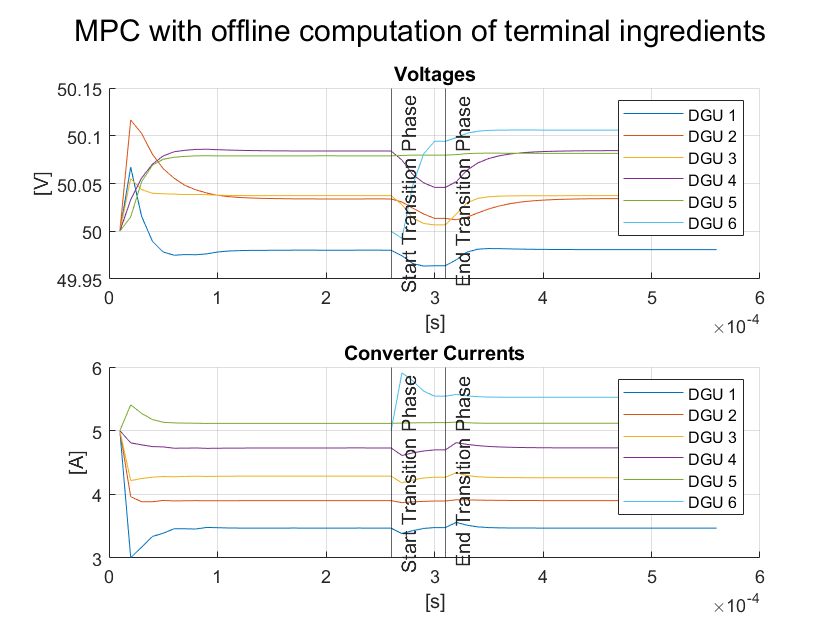

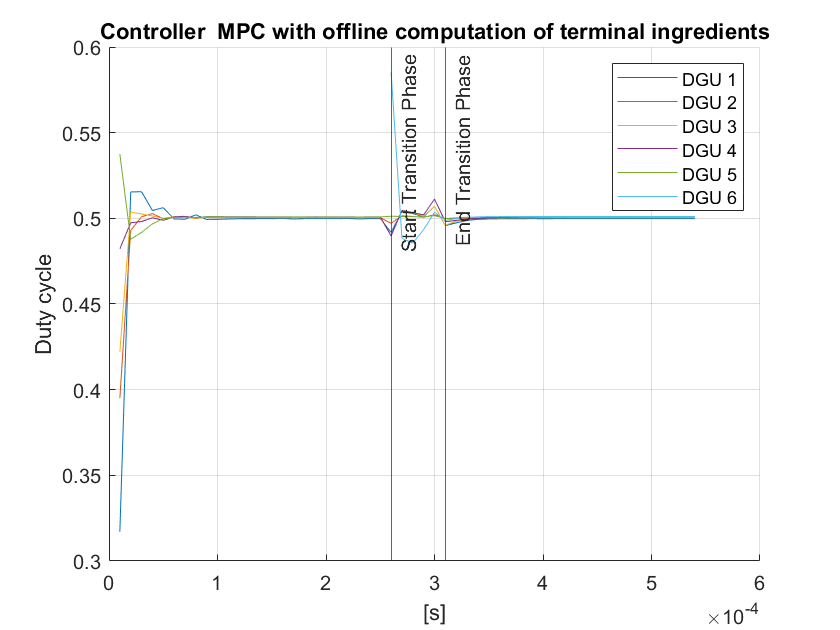

dguNet2.plot_DGU_system([X(1:end-1),X2_trans,X2],[U, U2_trans, U2], config, control_type, dguNet2, simStart, activeDGU_scen2, annot2plot); % plot results

#### Test PnP with offline terminal ingredients

dguNet_delta = dguNet_delta.setActiveDGU(activeDGU_scen2); 
dguNet2_delta = dguNet2;
delta_config = true;
dguNet2_delta = dguNet2_delta.compute_Ref_Constraints(delta_config);
use_passivity = false;
[x0_delta, Q_Ni, Ri, Qi] = utils.tuningParam(dguNet2_delta, delta_config, use_passivity);
[dguNet2_delta, Gamma_Ni, alpha_i] = offlineComputeTerminalSet(Q_Ni, Ri, dguNet2_delta);

ans = "Local feedback control laws K_N1"

   1.0e-03 *

         0         0    0.3814         0



ans = "Local feedback control laws K_N2"

   1.0e-03 *

    0.5724    0.0000         0         0    0.2862    0.0000    0.5724    0.0000



ans = "Local feedback control laws K_N3"

   1.0e-03 *

    0.2555   -0.0000         0         0    0.3194   -0.0000    0.3252         0



ans = "Local feedback control laws K_N4"

   1.0e-03 *

    0.4615   -0.0000         0         0



ans = "Local feedback control laws K_N5"

   1.0e-03 *

    0.2591         0         0         0



ans = "Local feedback control laws K_N6"

   1.0e-03 *

    0.2937         0         0         0



fprintf("Initial terminal set constrait alpha = %d \n", alpha_i)

Initial terminal set constrait alpha = 1.269610e-01 


alpha = alpha_i*ismember(1:6, dguNet2_delta.activeDGU)';
length_sim = 30;
[X2trans_delt, U2trans_delt,lenSim, xs,us] = PnP.transitionPhaseDeltaADMM(x0_delta, dguNet_delta,...
                                  dguNet2_delta, Qi, Ri, 'reference', alpha);

Iteration 1,  Time elapsed for each iteration 2.374600e-03 
Iteration 2,  Time elapsed for each iteration 2.279900e-03 
Iteration 3,  Time elapsed for each iteration 2.515700e-03 
Iteration 4,  Time elapsed for each iteration 2.383900e-03 
Iteration 5,  Time elapsed for each iteration 2.165600e-03 
Iteration 6,  Time elapsed for each iteration 1.952800e-03 
Iteration 7,  Time elapsed for each iteration 2.322600e-03 
Iteration 8,  Time elapsed for each iteration 2.072600e-03 
Iteration 9,  Time elapsed for each iteration 1.996500e-03 
Iteration 10,  Time elapsed for each iteration 2.070100e-03 
Iteration 11,  Time elapsed for each iteration 1.960500e-03 
Iteration 12,  Time elapsed for each iteration 3.432000e-03 
Iteration 13,  Time elapsed for each iteration 3.520900e-03 
Iteration 14,  Time elapsed for each iteration 2.270800e-03 
Iteration 15,  Time elapsed for each iteration 3.387300e-03 
Iteration 16,  Time elapsed for each iteration 3.987900e-03 
Iteration 17,  Time elapsed for e

for i = activeDGU_scen2
    x0_delt{i} = X2trans_delt{end}(:,i);   
end
lenSim2 = 25;
annot2plot.array = dguNet2_delta.Ts*[simStart2,simStart2+lenSim];
annot2plot.text = {'Start Transition Phase', 'End Transition Phase'};
control_type = "MPC with offline terminal ingredients";
[X2delt, U2delt] = PnP.mpc_sim_DGU_delta(@mpc_delta_admm, x0_delt, lenSim2, dguNet2_delta,...
                         alpha, Q_Ni, Ri, Gamma_Ni);

--INFO: Using controller mpc_delta_admm -- 
 ---- Simulation step 1 ---- 
Time elapsed to converge 1.637008e-01 and number of iterations 12 
---- Simulation step 2 ---- 
Time elapsed to converge 1.190480e-01 and number of iterations 9 
---- Simulation step 3 ---- 
Time elapsed to converge 9.294430e-02 and number of iterations 7 
---- Simulation step 4 ---- 
Time elapsed to converge 8.096480e-02 and number of iterations 5 
---- Simulation step 5 ---- 
Time elapsed to converge 6.313440e-02 and number of iterations 4 
---- Simulation step 6 ---- 
Time elapsed to converge 2.388750e-02 and number of iterations 1 
---- Simulation step 7 ---- 
Time elapsed to converge 2.567480e-02 and number of iterations 1 
---- Simulation step 8 ---- 
Time elapsed to converge 2.464870e-02 and number of iterations 1 
---- Simulation step 9 ---- 
Time elapsed to converge 1.227680e-02 and number of iterations 0 
---- Simulation step 10 ---- 
Time elapsed to converge 1.110100e-02 and number of iterations 0 
---

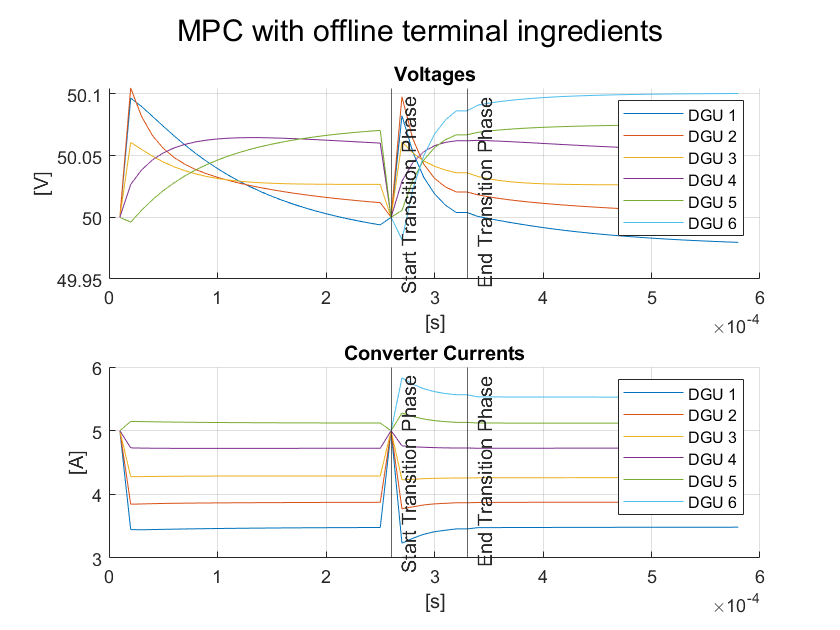

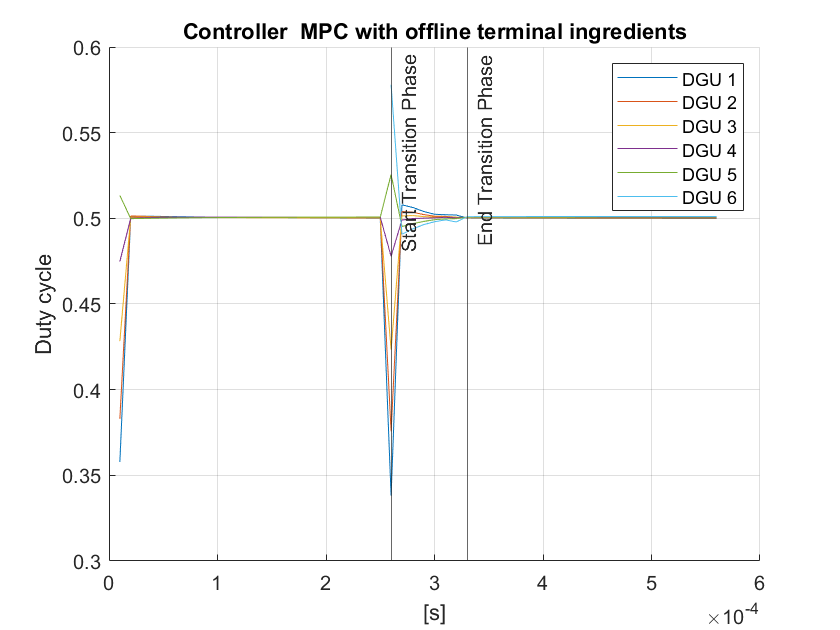

dguNet2.plot_DGU_system([Xdelt(1:end-1),X2trans_delt,X2delt],...
                        [Udelt, U2trans_delt, U2delt], config, control_type, dguNet2_delta, simStart, ...
                        activeDGU_scen2, annot2plot); % plot results

#### C) 3rd Scenario: Plug out DGU 4

% activeDGU_scen3 = [1 2 3 5 6]; % remove DGU 4 from active DGU list
% dguNet3 = dguNet2; % copy the previous instance with 6 DGUs and create new instance for this scenario
% dguNet3 = dguNet3.setActiveDGU(activeDGU_scen3);
% dguDelete = 4;
% Rij_mat(dguDelete,:) = 0; Rij_mat(:,dguDelete) = 0;
% dguNet3 = dguNet3.setConnectionsGraph(Rij_mat);
% dguNet3 = dguNet3.initDynamics();
% plot(dguNet3.NetGraph, 'EdgeLabel', dguNet3.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
%       'MarkerSize', 7);
% title('Scenario where DGU 4 is to be plugged out')
% dguNet3 = dguNet3.compute_Ref_Constraints(delta_config);

- **Redesign Phase**: Compute new $K_i$ and $P_i$ of neighbors set of DGU 4

% dguNet3 = PnP.redesignPhase(dguNet3, dguNet2.NetGraph, dguDelete, "delete");

- **Transition Phase**: Take as initial state the end of simulation of scenario 2

% % call again since dimension of Q_Ni change when adding/removing DGU
% [~, Q_Ni, Ri, Qi] = utils.tuningParam(dguNet3, delta_config);
% for i = activeDGU_scen2
%     x0{i} = X2{end}(:,i);   
% end
% disp('x0'); celldisp(x0);

Define new references, to see the effect of the objective function of the optimization problem:

% dguNet3.Vr = linspace(49.90, 50.4, nb_subsystems);% references
% dguNet3.Il = linspace(2.5, 7.5, nb_subsystems);
% dguNet3 = dguNet3.compute_Ref_Constraints(delta_config);

$f^i (x_s^i , u_s^i, x^i) = {||x_s^i - x_0^i ||}^2$ will keep the steady state as close as possible to the current state: for quick P&P operation

% ADMM = true;
% [X3_trans_,U3_trans_,lenTrans_, xs_,us_,alpha_]= PnP.transitionPhase(x0, dguNet2, dguNet3, Qi, Ri, 'current state', ADMM)

$f^i (x_s^i , u_s^i, x^i) = {||x_s^i - x_r^i ||}^2$ will keep the steady state as close as possible from the references, with the goal of reducing modification to the desired system behaviour

% [X3_trans,U3_trans,lenTrans, xs,us,alpha]= PnP.transitionPhase(x0, dguNet2, dguNet3, Qi, Ri, 'reference', ADMM)

If P&P permitted, simulate normal operation of the network after plug out of DGU 4:

% for i = activeDGU_scen3
%     x0{i} = X3_trans{end}(:,i);   
% end
% lenSim3 = 20;
% [X3, U3] = PnP.mpc_DGU_tracking(@trackingMPC_reconf_admm, x0, lenSim3, dguNet3, Q_Ni, Ri);
% annot2plot.array = dguNet3.Ts*[11,11+lenTrans];
% annot2plot.text = {'Start Transition Phase', 'End Transition Phase'};
% % plot the last 11 points from the previous phase
% dguNet3.plot_DGU_system([X2(end-10:end), X3_trans, X3],[U2(end-10:end), U3_trans, U3], config, ...
%                 control_type, dguNet3, simStart, activeDGU_scen2, annot2plot); % plot results